% Jeremiah Sullivan
% EC508, Wireless Communicaton
% Mini Project 3, April 2019
clc; close all; clear all;
%% Slow Fading Channels
% Consider a SIMO channel with L receive antennas,
%       y[m] = h x[m]+w[m]
%           where w[m] is i.i.d. CN (0, N_{0}I),
%           x[m] satisfies power constraint P,
%           h ~ CN (0, I) and is known only to the receiver.


%% Part A
% To get started, write code to compute the closed-form outage capacity
% that we derived in class for the L = 1 case.
% Additionally, write code to find the outage capacity empirically.
%   For SNR = 0dB to 20dB (with 1dB spacing)
%   plot the capacity curves from these two methods for pout = 0.01, 0.05, 0.1.
%   (If you?ve done everything right, they should coincide.)
pOut    = [0.01, 0.05, 0.1];  SNRdb = 0:20;
SNR      = 10.^(SNRdb/10);
L          =     1;    % Diversity
M         = 5E5; % 1E6 == detailed, 1E5 == fast
h          = 1/sqrt(2) * randn(L,M) + 1j/sqrt(2) * randn(L,M);
hd        = sort(abs(h).^2); 
fprintf('The channel gains have a mean of %01.4f and a standard deviation of %1.4f', abs(mean(h)), std(h))

The channel gains have a mean of 0.0009 and a standard deviation of 1.0009

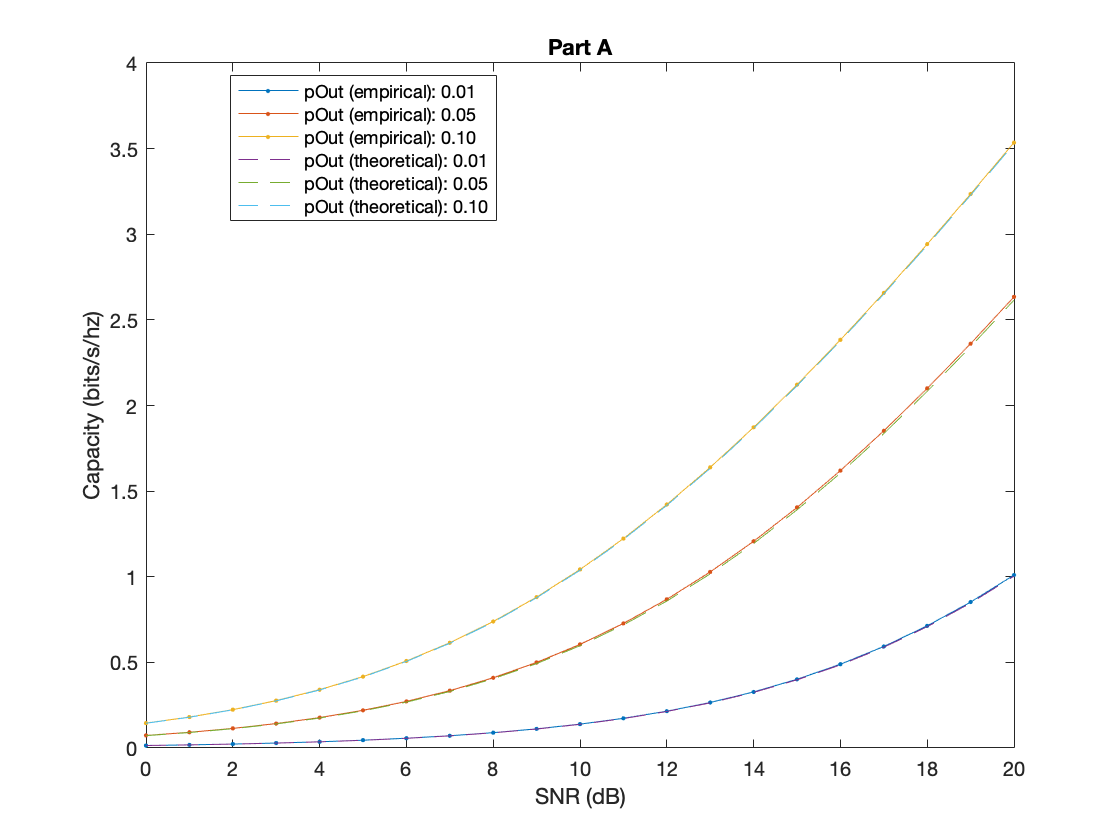


C = zeros(length(pOut), length(SNRdb));
for i = 1:length(pOut)
    E           = log2(1 + hd' .*SNR);
    Es          = sort(E);            % sort them in ascending order
    C(i,:)      = Es(M*pOut(i),:);    % take the value of the sorted trial in position pout×M.
end
figure;
plot(SNRdb, (C), '.-'); xlabel('SNR (dB)'); ylabel('Capacity (bits/s/hz)');
exactC = log2(1 + log( 1 ./ (1 - pOut')).*SNR);
hold on; plot(SNRdb, exactC, '--'); title('Part A');
legend([sprintfc('pOut (empirical): %01.2f', pOut'); (sprintfc('pOut (theoretical): %01.2f', pOut'))], 'location', 'best')

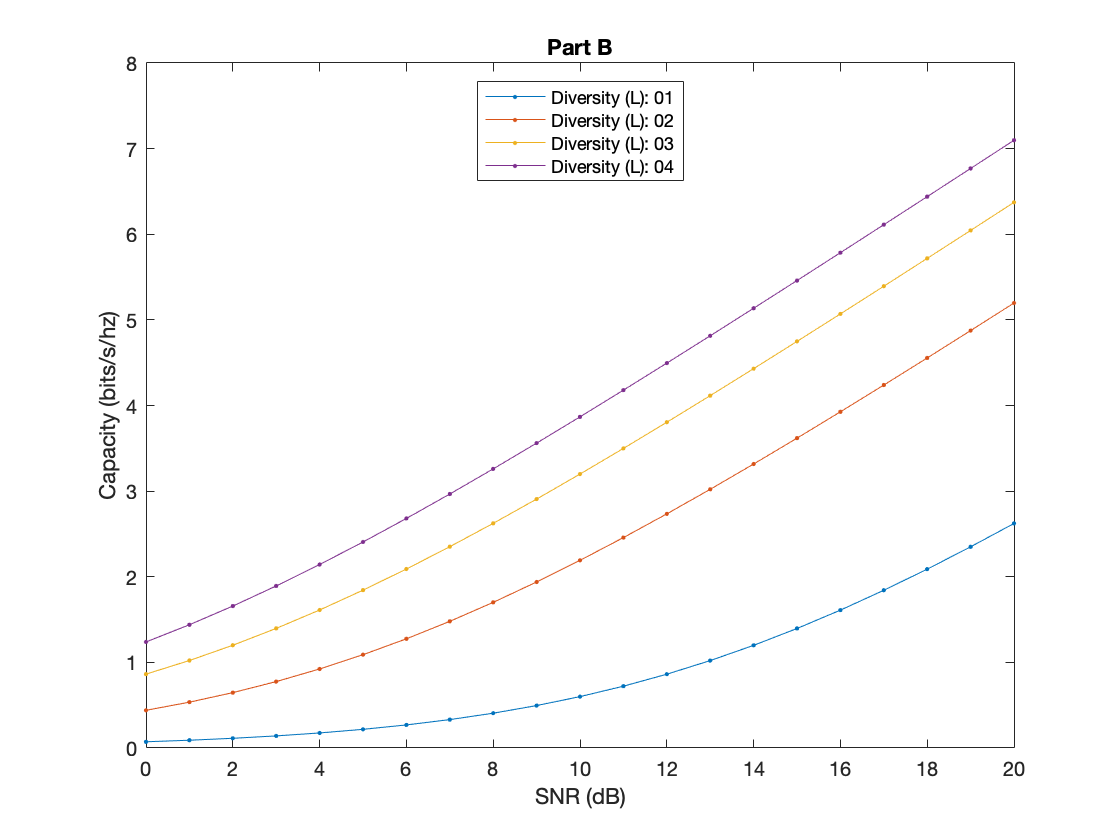


%% Part B
%  Generalize to any L
pOut = 0.05;
figure; clear C E Es;
L = 1:4;
for j = 1:length(L)
    h        = 1/sqrt(2) * randn(L(j),M) + 1j/sqrt(2) * randn(L(j),M); % Should be LxN
    hD       = sort(sum(abs(h).^2,1));
    for i = 1:length(pOut)
        E          = log2(1 + hD' .*SNR);  % Each SNR should form a column (ie, MxSNR);
        C(j,:)     = E(M*pOut(i),:);                                 % take the value of the sorted trial in position pout×M.
    end
end
plot(SNRdb, (C), '.-'); hold on;
xlabel('SNR (dB)'); ylabel('Capacity (bits/s/hz)'); title('Part B');
legend(sprintfc('Diversity (L): %02.0f', L), 'location', 'best');

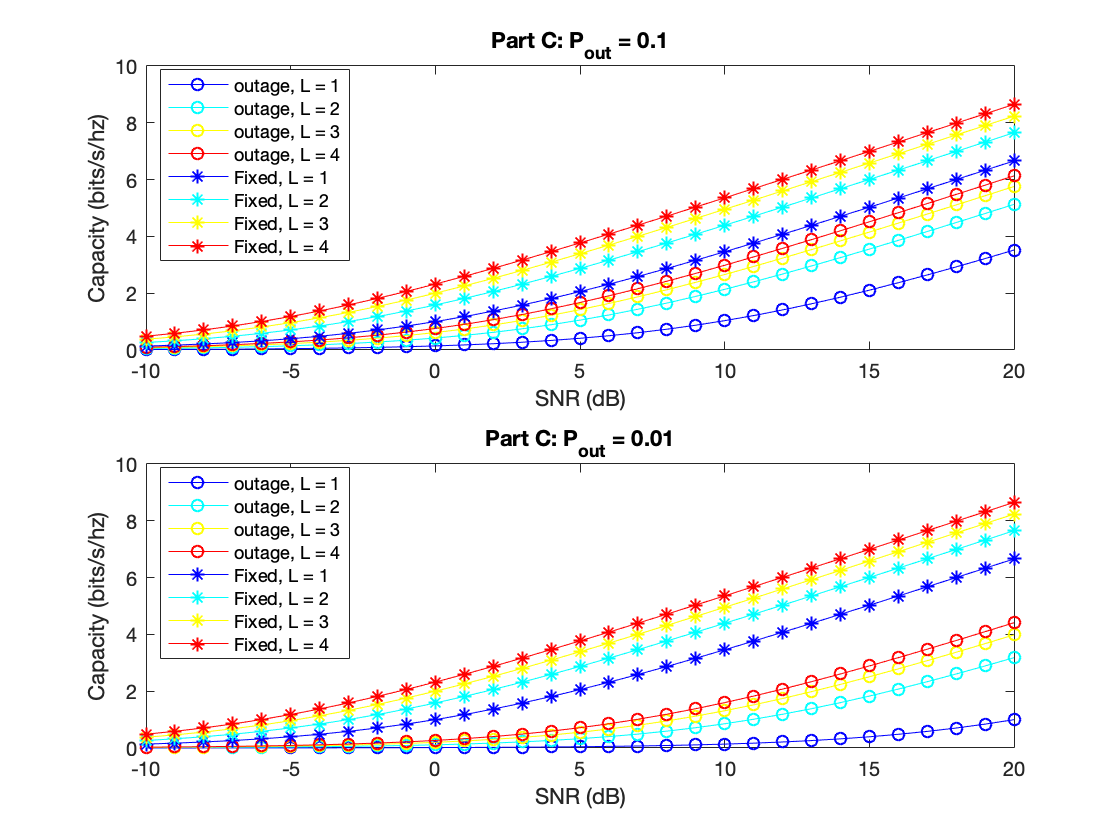


%% Part C:
% Outage Capacity vs. Fixed Capacity
% Confused by ||h||^2 = L
SNRdb = -10:20; SNR = 10.^(SNRdb./10);
pOut    = [0.1, 0.01];
for i = 1:length(pOut)
    for j = 1:length(L)
        h        = 1/sqrt(2) * randn(j,M) + 1j/sqrt(2) * randn(j,M); % Should be LxN
        hD     = sort(abs(sum(h.^2,1)));
        E          = log2(1 + hD' .*SNR);  % Each SNR should form a column (ie, MxSNR);
        Co(j,:)   = E(M*pOut(i),:);                                 % take the value of the sorted trial in position pout×M.
        Cf(j,:)    = log2(1 + SNR*L(j));
    end
    subplot(2,1,i);h1 =  plot(SNRdb, (Co), 'o-'); hold on; h2 = plot(SNRdb, Cf, '*-');
    set(h1,{'color'}, num2cell(jet(4),2)); set(h2, {'color'}, num2cell(jet(4),2));
    xlabel('SNR (dB)'); ylabel('Capacity (bits/s/hz)');
    title(['Part C: P_{out} = ', num2str(pOut(i))]);
    a = strings(8,1);
    a(1:4,:) = 'outage, L = ' ; a(5:end, :) = 'Fixed, L = ';
    for ii = 1:8; b(ii,:) = strcat(a(ii,:), num2str(mod(ii-1, 4)+1)); end
    legend(sprintfc('%s',  b), 'location', 'best');
end

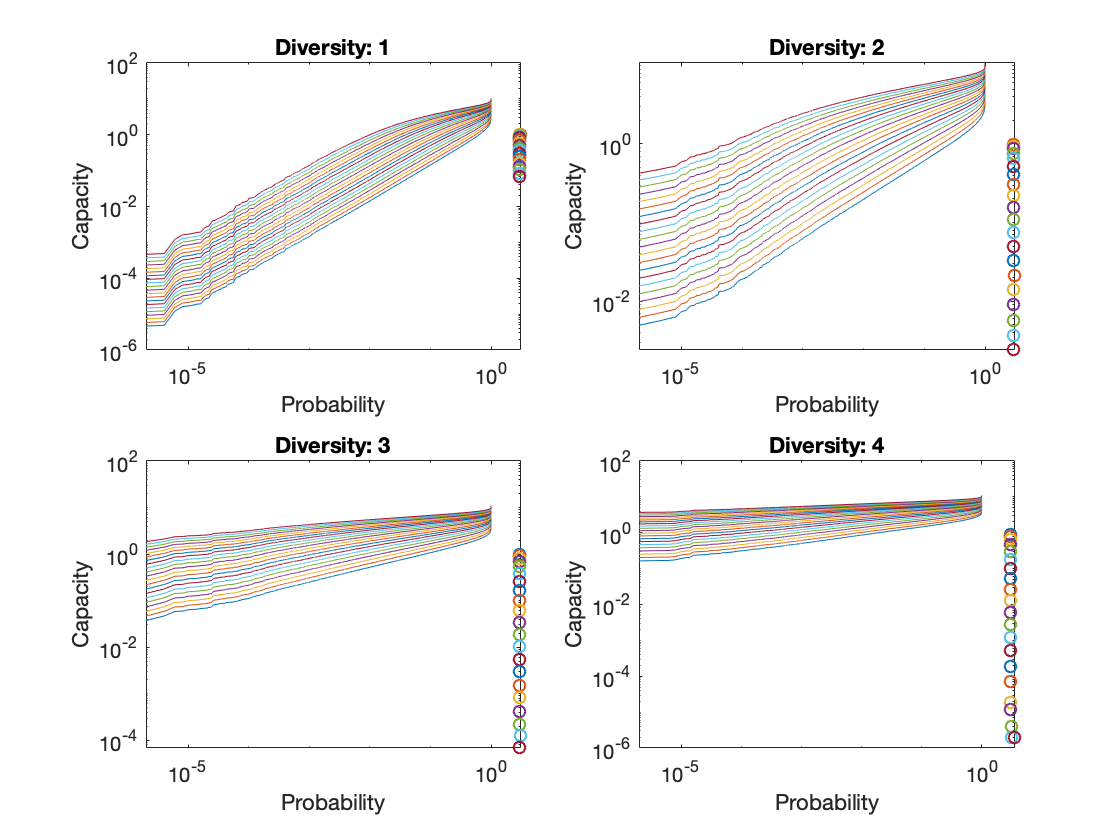


%% Convert to ratio... ^^
% TEXT START
% In low SNR regions, the capacity converges to zero.
% Thus the diversity is most beneficial with high SNR
% TEXT END


%% Fix target rate
figure; clc;
SNRdb = 0:20; SNR = 10.^(SNRdb./10); L = 1:4;
R = 3; pOut = zeros(length(L), length(SNR));
for j = 1:length(L)
    h        = 1/sqrt(2) * randn(L(j),M) + 1j/sqrt(2) * randn(L(j),M); % Should be LxN
    hD     = sort(sum(abs(h).^2,1));
    E        = log2(1 + hD' .*SNR);  % Each SNR should form a column (ie, MxSNR);
    if ~all((R > min(E)) & R< max(E)); warning([ 'Requested value not in range. L = ' num2str(L(j))]); end
    [~, I]  = min(abs(E - R));   % Find the closest value
    pOut(j, :) = I/M;                       % Transform that value into a probability
    if 1 % DEBUG
        subplot(2,2,j);
        loglog(linspace(0,1, length(h)),  E); hold on;
        xlabel('Probability');  ylabel('Capacity');
        for i = 1:length(SNR)
            plot(E(I(i), i), I(i)./length(h), 'o');
        end
        title(['Diversity: ', num2str(L(j))]);
    end
end

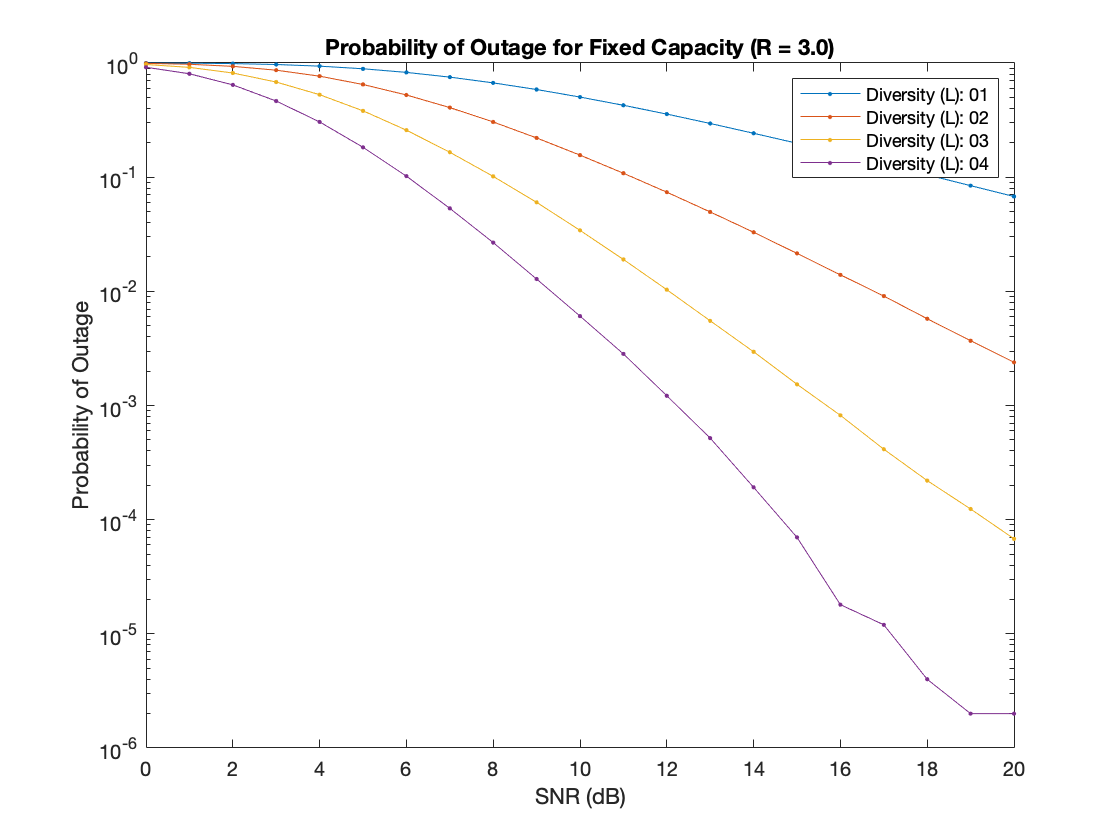

figure; semilogy(SNRdb, pOut, '.-'); legend(sprintfc('Diversity (L): %02.0f ', L)); 
xlabel('SNR (dB)'); ylabel('Probability of Outage'); title(sprintf('Probability of Outage for Fixed Capacity (R = %02.1f)', R)); 

% TEXT START
% This look like the curves for Probability of Error when sending a BPSK
% from mini-project 2. Essentially there appears to be diminishing returns
% when using higher and higher diversity levels. 
% TEXT END
%% PROBLEM 2
%}
%}